clear;
addChenFunction;

added Chen Functions



dicPath = uigetdir('D:\WE43_T6_C1_insitu_compression\stitched_DIC','pick DIC directory, which contains the stitched DIC data for each stop');

% looks like have to include this part to read the sample name.
[fileSetting,pathSetting] = uigetfile('D:\p\m\DIC_Analysis\setting_for_real_samples\WE43_T6_C1_setting.mat','select setting file which contains sampleName, stopNames, FOVs, translations, etc');
load_settings([pathSetting,fileSetting],'sampleName','cpEBSD','cpSEM','sampleMaterial','stressTensor','strainPauses');

% load previous data and settings
saveDataPath = [uigetdir('D:\WE43_T6_C1_insitu_compression\Analysis_by_Matlab_after_realign','choose a path of the saved processed data, or WS, or etc.'),'\'];
saveDataPathInput = saveDataPath;
load([saveDataPath,sampleName,'_traceAnalysis_WS_settings.mat']);
if ~strcmpi(saveDataPath,saveDataPathInput)
    disp('Input saveDataPath is different from that saved in setting.mat file. Check files or code.');
    return;
end

% Load from the pre-labeled results: twinMap, sfMap, struCell.  (cToGbDistMap is omitted, as will no longer be used in this code)
[confirmedLabelFile, confirmedLabelPath] = uigetfile('D:\p\m\DIC_Analysis\*.mat','select the results where twin identification was based on trace dir and strain');
[twinGbIntersectionFile, twinGbIntersectionPath] = uigetfile('D:\p\m\DIC_Analysis\temp_results\*.mat','select the results for twin-grain boundary intersection');

try
    load([saveDataPath,sampleName,'_EbsdToSemForTraceAnalysis'],'X','Y','boundaryTF','boundaryTFB','uniqueBoundary','uniqueBoundaryList','ID','gID','gExx','gPhi1','gPhi','gPhi2','gNeighbors','gNNeighbors');
    dataFile = matfile([saveDataPath,sampleName,'_EbsdToSemForTraceAnalysis']);
catch
    load([saveDataPath,sampleName,'_EbsdToSemForTraceAnalysis_GbAdjusted'],'X','Y','boundaryTF','boundaryTFB','uniqueBoundary','uniqueBoundaryList','ID','gID','gExx','gPhi1','gPhi','gPhi2','gNeighbors','gNNeighbors');
    dataFile = matfile([saveDataPath,sampleName,'_EbsdToSemForTraceAnalysis_GbAdjusted']);
end
% modify / or keep an eye on these settings for the specific sample to analyze  ------------------------------------------------------------------------------------
STOP = {'0','1','2','3','4','5','6','7'};
B=1;    % 0-based B=1.  1-based B=0.
iE_start = 2;   % elongation levels to analyze. 0-based.
iE_stop = 5;

% file name prefixes
f1 = 'WE43_T6_C1_s';
f2 = '_';

debugTF = 0;

%% [data] strain data. Convert into v7.3 for partial loading
%%
clear strainFile;
for iE = iE_start-1:iE_stop
    strainFileName = [dicPath,'\',f2,STOP{iE+B}];
    disp(strainFileName);
    if ~exist([strainFileName,'_v73.mat'],'file')
        load(strainFileName);
        clear('exy_corrected');
        load(strainFileName,'exy_corrected');   % if 'exy_corrected' does not exist, this does not give error, rather, just warning.
        
        if exist('exy_corrected','var')&&(1==exy_corrected)
            disp('================= exy already corrected ! ========================');
            exy_corrected = 1;
        else
            disp('================= exy being corrected here ! =======================');
            exy = -exy;
            exy_corrected = 1;
        end
        % remove bad data points
        exx(sigma==-1) = nan;
        exy(sigma==-1) = nan;
        eyy(sigma==-1) = nan;
        qt_exx = quantile(exx(:),[0.0013,0.9987]); qt_exx(1)=min(-1,qt_exx(1)); qt_exx(2)=max(1,qt_exx(2));
        qt_exy = quantile(exy(:),[0.0013,0.9987]); qt_exy(1)=min(-1,qt_exy(1)); qt_exy(2)=max(1,qt_exy(2));
        qt_eyy = quantile(eyy(:),[0.0013,0.9987]); qt_eyy(1)=min(-1,qt_eyy(1)); qt_eyy(2)=max(1,qt_eyy(2));
        ind_outlier = (exx<qt_exx(1))|(exx>qt_exx(2))|(exy<qt_exy(1))|(exy>qt_exy(2))|(eyy<qt_eyy(1))|(eyy>qt_eyy(2));
        exx(ind_outlier) = nan;
        exy(ind_outlier) = nan;
        eyy(ind_outlier) = nan;
        
        outlier_removed = 1;
        save([strainFileName,'_v73.mat'],'outlier_removed','exy_corrected','-v7.3');
        
        myFile = matfile(strainFileName);
        myFields = who(myFile);
        for ii=1:length(myFields)
            save([strainFileName,'_v73.mat'],myFields{ii},'-append','-v7.3');
        end
    else
        disp('v7.3 file already exist');
    end
    strainFile{iE} = matfile([strainFileName,'_v73.mat']);
end

D:\WE43_T6_C1_insitu_compression\stitched_DIC\_1


v7.3 file already exist


D:\WE43_T6_C1_insitu_compression\stitched_DIC\_2


v7.3 file already exist


D:\WE43_T6_C1_insitu_compression\stitched_DIC\_3


v7.3 file already exist


D:\WE43_T6_C1_insitu_compression\stitched_DIC\_4


v7.3 file already exist


D:\WE43_T6_C1_insitu_compression\stitched_DIC\_5


v7.3 file already exist



%% (0) load data, using SF threshold values to assign active twin system, and make maps
% Load cluster number maps (cleaned).
clusterNumberMapCell = cell(1,length(STOP)-1);
for iE = []                                         %iE_start:iE_stop
    fName_c2t_result = [sampleName,'_s',num2str(STOP{iE+B}),'_cluster_to_twin_result.mat'];
    load([saveDataPath,fName_c2t_result],'clusterNumMapCleaned');
    clusterNumberMapCell{iE} = clusterNumMapCleaned;
end

% Load from the pre-labeled results: twinMapCell, sfMapCell, struCell.  (cToGbDistMapCell is omitted, as will no longer be used in this code)
% load(fullfile(confirmedLabelPath,confirmedLabelFile),'struCell','twinMapCell','trueTwinMapCell','sfMapCell','tNote');
% load(fullfile(confirmedLabelPath,confirmedLabelFile),'trueTwinMapCell');
trueTwinFile = matfile(fullfile(confirmedLabelPath,confirmedLabelFile));

% load previous twin_gb interaction result
load(fullfile(twinGbIntersectionPath, twinGbIntersectionFile));



**(3) Now, something interesting.  We categorize the grain boundary into different groups, and look at how twinning activity is affected by the neighboring grains at these grain boundaries.  **

for iE = 2:5
    % For each grain, summarize a [b#,g#] pair for distMap purpose, for each twin activity.
    % Also, generate one data point from the mantle, contribution to one of the previous defined regions.
    
    NN = 250;
    x_dist = (1:NN)';
    qs_target = [0.0014, 0.0227, 0.1587, 0.5, 0.8414, 0.9772, 0.9987];
    mm = 0;
    MM = 150;
    % The analysis takes time, but we may directly load some results.
    try
        load(['temp_results/quants_wrt_gb_',num2str(iE),'.mat']);
    catch
        error("cannot load");
    end
    
    %% can plot distance map to illustrate
    if 0
        myplot(distMap_not_involved,boundaryTFB + logical(trueTwinMapCell{iE}));
        myplot(distMap_slip_twin_a,boundaryTFB + logical(trueTwinMapCell{iE}));
        myplot(distMap_slip_twin_b,boundaryTFB + logical(trueTwinMapCell{iE}));
        myplot(distMap_co_found,boundaryTFB + logical(trueTwinMapCell{iE}));
        myplot(distMap_twin_twin_a,boundaryTFB + logical(trueTwinMapCell{iE}));
        myplot(distMap_twin_twin_b,boundaryTFB + logical(trueTwinMapCell{iE}));
        myplot(distMap_slip_growth_a,boundaryTFB + logical(trueTwinMapCell{iE}));
        myplot(distMap_slip_growth_b,boundaryTFB + logical(trueTwinMapCell{iE}));
        myplot(distMap_co_growth,boundaryTFB + logical(trueTwinMapCell{iE}));
    end


**The effect of high strain on twin growth/activation:**

**Here we plot the median/mean/etc of effective strain for all data points at distances=1,2,3,... to gb, for different categories**

**--> If we have slip on one side of gb, and twinning on the otherside.  At the previous strain level, slip side strain was highest.**

**--> slip-slip, and slip side of slip-new twin pair, also tend to have high strain.**

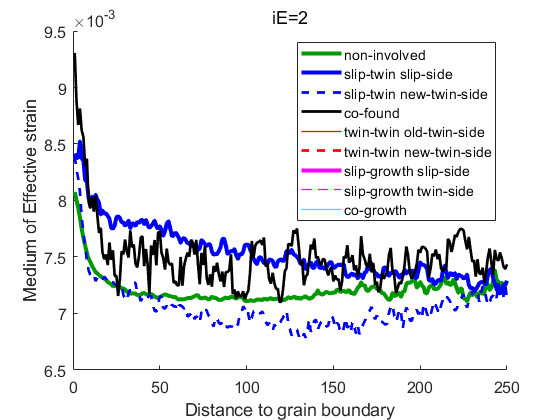

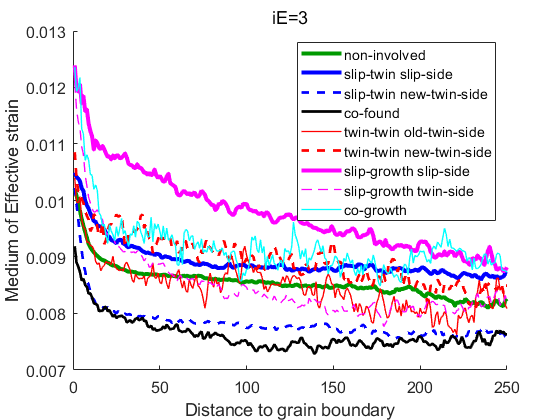

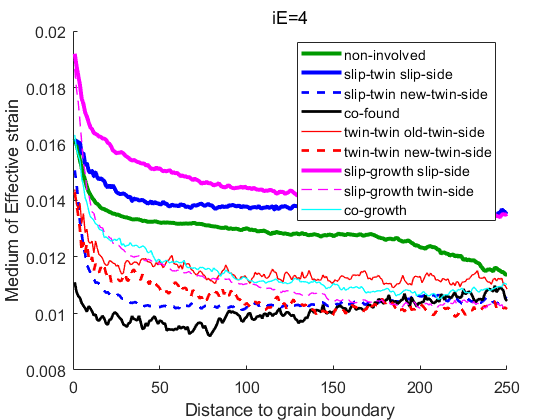

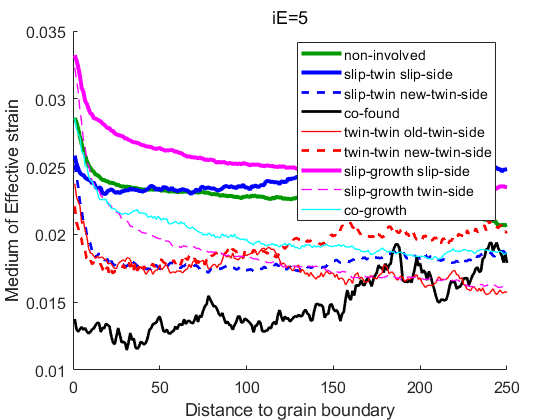

    ith = 4;
    figure;disableDefaultInteractivity(gca); hold on;
    nPts = length(x_dist);    % or 150
    % ndp_to_plot = 150;
    plot(x_dist(1:nPts),q_not_involved(ith,1:nPts),'-','color',[0 0.6 0],'LineWidth',3);
    plot(x_dist(1:nPts),q_slip_twin_a(ith,1:nPts),'-b','LineWidth',3);
    plot(x_dist(1:nPts),q_slip_twin_b(ith,1:nPts),'--b','LineWidth',2);
    
    plot(x_dist(1:nPts),q_co_found(ith,1:nPts),'-k','LineWidth',2);
    plot(x_dist(1:nPts),q_twin_twin_a(ith,1:nPts),'-r','LineWidth',1);
    plot(x_dist(1:nPts),q_twin_twin_b(ith,1:nPts),'--r','LineWidth',2);
    
    plot(x_dist(1:nPts),q_slip_growth_a(ith,1:nPts),'-m','LineWidth',3);
    plot(x_dist(1:nPts),q_slip_growth_b(ith,1:nPts),'--m','LineWidth',1);
    plot(x_dist(1:nPts),q_co_growth(ith,1:nPts),'-c','LineWidth',1);
    
    legend({'non-involved','slip-twin slip-side','slip-twin new-twin-side', 'co-found','twin-twin old-twin-side','twin-twin new-twin-side', 'slip-growth slip-side','slip-growth twin-side','co-growth'});
    set(gca,'fontsize',12);
    xlabel('Distance to grain boundary');
    if ith==4
        ylabel('Medium of Effective strain');
    elseif ith==8
        ylabel('Mean Effective strain');
    end
    title(['iE=',num2str(iE)],'fontweight','normal');
    
end

**For each category, take all data points in all grains within a mantle of size <150 to gb, use a boxplot to show the strain distribution.**

**The trend is similar, e.g., the slip side of slip-twin growth region tend to have the highest strain.**

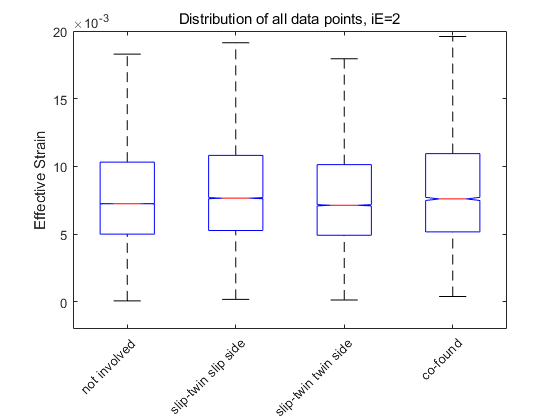

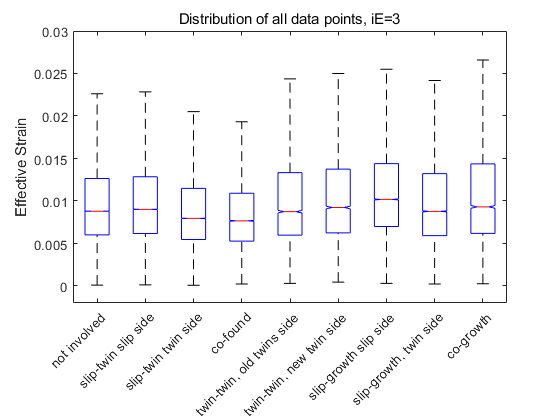

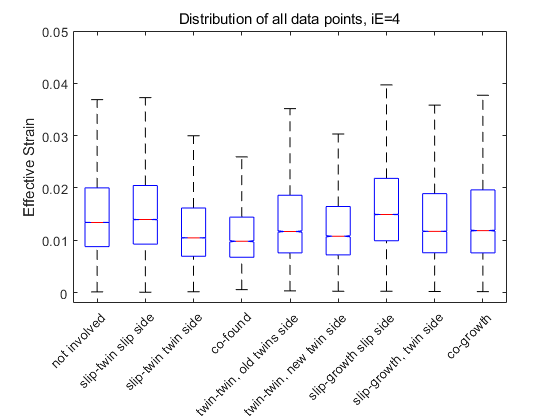

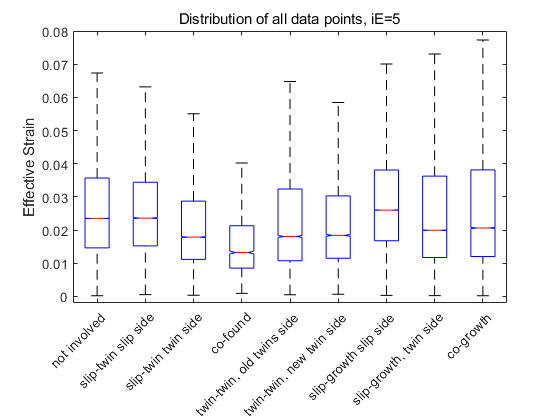

%% boxplot to summarize the strain distribution in a mantle of [0,150] data point size, for different types of regions.
% (1) not involved, (2) slip-induced-twin, slip side, (3) slip-induced-twin, twin side,
% (4) co-found, (5) twin-induced-twin, old twin side, (6) twin-induced-twin, new twin side,
% (7) slip-induced-growth, slip side, (8) slip-induced-growth, twin side, (9) co-growth
yLimits = [nan, nan;
    -0.002, 0.02;
    -0.002, 0.03;
    -0.002, 0.05;
    -0.002, 0.08];
for iE=2:5
    try
        load(['temp_results/quants_wrt_gb_',num2str(iE),'.mat']);
    catch
        error("cannot load");
    end
    eMap = calculate_effective_strain(strainFile{iE-1}.exx, strainFile{iE-1}.exy, strainFile{iE-1}.eyy);
    mm = 0;
    MM = 150;
    v = [];
    g = [];
    ind = (distMap_not_involved>mm)&(distMap_not_involved<MM);
    v = [v; eMap(ind)];
    g = [g; 1*ones(sum(ind(:)),1)];
    ind = (distMap_slip_twin_a>mm)&(distMap_slip_twin_a<MM);
    v = [v; eMap(ind)];
    g = [g; 2*ones(sum(ind(:)),1)];
    ind = (distMap_slip_twin_b>mm)&(distMap_slip_twin_b<MM);
    v = [v; eMap(ind)];
    g = [g; 3*ones(sum(ind(:)),1)];
    
    ind = (distMap_co_found>mm)&(distMap_co_found<MM);
    v = [v; eMap(ind)];
    g = [g; 4*ones(sum(ind(:)),1)];
    ind = (distMap_twin_twin_a>mm)&(distMap_twin_twin_a<MM);
    v = [v; eMap(ind)];
    g = [g; 5*ones(sum(ind(:)),1)];
    ind = (distMap_twin_twin_b>mm)&(distMap_twin_twin_b<MM);
    v = [v; eMap(ind)];
    g = [g; 6*ones(sum(ind(:)),1)];
    
    ind = (distMap_slip_growth_a>mm)&(distMap_slip_growth_a<MM);
    v = [v; eMap(ind)];
    g = [g; 7*ones(sum(ind(:)),1)];
    ind = (distMap_slip_growth_b>mm)&(distMap_slip_growth_b<MM);
    v = [v; eMap(ind)];
    g = [g; 8*ones(sum(ind(:)),1)];
    ind = (distMap_co_growth>mm)&(distMap_co_growth<MM);
    v = [v; eMap(ind)];
    g = [g; 9*ones(sum(ind(:)),1)];
    
    figure;disableDefaultInteractivity(gca);
    % reduce number of points to plot faster
    boxplot(v(1:100:end),g(1:100:end),'Notch','on','symbol','');
    set(gca,'ylim',yLimits(iE,:));
    set(gca,'xticklabel',{'not involved','slip-twin slip side','slip-twin twin side',...
        'co-found','twin-twin, old twins side','twin-twin, new twin side',...
        'slip-growth slip side','slip-growth, twin side','co-growth'},'xticklabelrotation',45);
    ylabel('Effective Strain');
    title(['Distribution of all data points, iE=',num2str(iE)],'fontweight','normal');
end

**In a similar way, in the code above, for each grain, calculate the quantiles of all data points' strain within a distance [0,150] to the boundary of the specific category.  Then for each category, summarize by boxplot to show the distribution of these quantiles/etc.**

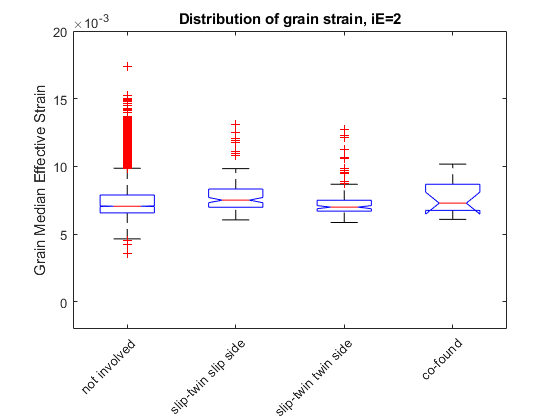

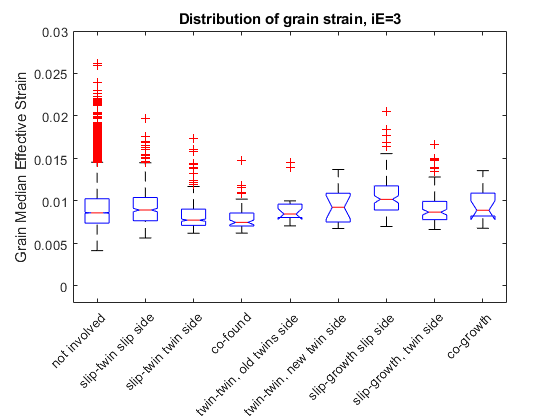

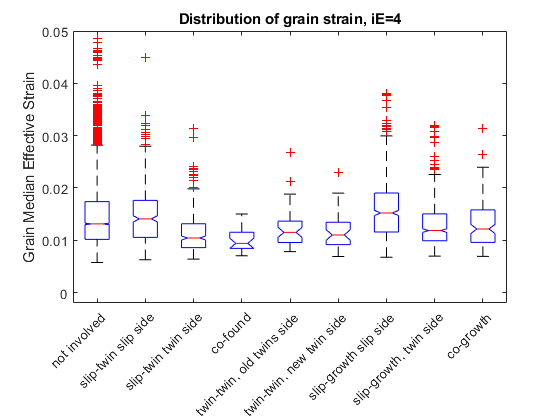

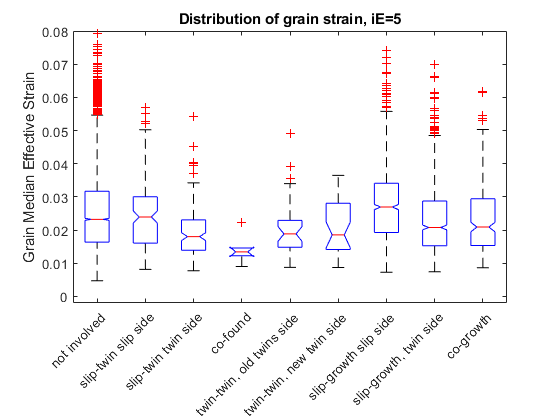

%% For each grain, generate one data point from the mantle, contribution to one of the previous defined regions.  Could combine, but maybe better to run each section for each method.
% (1) not involved, (2) slip-induced-twin, slip side, (3) slip-induced-twin, twin side,
% (4) co-found, (5) twin-induced-twin, old twin side, (6) twin-induced-twin, new twin side,
% (7) slip-induced-growth, slip side, (8) slip-induced-growth, twin side, (9) co-growth
yLimists = [nan, nan;
    0.002, 0.02;
    0.002, 0.03;
    0.002, 0.05;
    0.002, 0.08];
ith = 4;
for iE=2:5
    try
        load(['temp_results/quants_wrt_gb_',num2str(iE),'.mat']);
    catch
        error("cannot load");
    end
    
    vv = [];
    gg = [];
    try
        vv = [vv;qList_not_involved(:,ith)];
        gg = [gg; 1 * ones(size(qList_not_involved,1),1)];
    catch
    end
    try
        vv = [vv;qList_slip_twin_a(:,ith)];
        gg = [gg; 2 * ones(size(qList_slip_twin_a,1),1)];
    catch
    end
    try
        vv = [vv;qList_slip_twin_b(:,ith)];
        gg = [gg; 3 * ones(size(qList_slip_twin_b,1),1)];
    catch
    end
    try
        vv = [vv;qList_co_found(:,ith)];
        gg = [gg; 4 * ones(size(qList_co_found,1),1)];
    catch
    end
    try
        vv = [vv;qList_twin_twin_a(:,ith)];
        gg = [gg; 5 * ones(size(qList_twin_twin_a,1),1)];
    catch
    end
    try
        vv = [vv;qList_twin_twin_b(:,ith)];
        gg = [gg; 6 * ones(size(qList_twin_twin_b,1),1)];
    catch
    end
    try
        vv = [vv;qList_slip_growth_a(:,ith)];
        gg = [gg; 7 * ones(size(qList_slip_growth_a,1),1)];
    catch
    end
    try
        vv = [vv;qList_slip_growth_b(:,ith)];
        gg = [gg; 8 * ones(size(qList_slip_growth_b,1),1)];
    catch
    end
    try
        vv = [vv;qList_co_growth(:,ith)];
        gg = [gg; 9 * ones(size(qList_co_growth,1),1)];
    catch
    end
    
    figure;disableDefaultInteractivity(gca);
    boxplot(vv,gg,'Notch','on');
    set(gca,'ylim',yLimits(iE,:));
    set(gca,'xticklabel',{'not involved','slip-twin slip side','slip-twin twin side',...
        'co-found','twin-twin, old twins side','twin-twin, new twin side',...
        'slip-growth slip side','slip-growth, twin side','co-growth'},'xticklabelrotation',45);
    ylabel('Grain Median Effective Strain');
    title(['Distribution of grain strain, iE=',num2str(iE)]);
end